# 提取信号幅度差

## 读取文件

clear
close all
% 文件路径
% 315
dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压';
% 203
% dirName = 'D:\file\Lab-Drive\Project\GPS_Backscatter\Data\0612测试集_3Tag_35Point\Tag2_Loc11';

FileTable = [
'152mV_101mV_gnss_log_2021_06_08_22_07_20.txt';
'152mV_106mV_gnss_log_2021_06_08_22_16_04.txt';
'152mV_110mV_gnss_log_2021_06_08_20_06_39.txt';
'152mV_110mV_gnss_log_2021_06_08_20_23_05.txt';
'152mV_111mV_gnss_log_2021_06_08_22_24_45.txt';
'152mV_116mV_gnss_log_2021_06_08_22_33_11.txt';
'152mV_122mV_gnss_log_2021_06_08_22_40_17.txt';
'152mV_126mV_gnss_log_2021_06_08_22_48_48.txt';
'152mV_132mV_gnss_log_2021_06_08_22_56_44.txt';
'152mV_132mV_gnss_log_2021_06_09_09_17_06.txt';
'152mV_132mV_gnss_log_2021_06_09_09_32_35.txt';
'152mV_132mV_gnss_log_2021_06_09_09_43_37.txt';
'152mV_046mV_gnss_log_2021_06_08_20_34_49.txt';
'152mV_052mV_gnss_log_2021_06_08_20_42_17.txt';
'152mV_056mV_gnss_log_2021_06_08_20_51_42.txt';
'152mV_062mV_gnss_log_2021_06_08_21_00_50.txt';
'152mV_068mV_gnss_log_2021_06_08_21_08_23.txt';
'152mV_073mV_gnss_log_2021_06_08_21_14_38.txt';
'152mV_080mV_gnss_log_2021_06_08_21_25_50.txt';
'152mV_085mV_gnss_log_2021_06_08_21_35_02.txt';
'152mV_090mV_gnss_log_2021_06_08_21_42_51.txt';
'152mV_090mV_gnss_log_2021_06_09_09_56_04.txt';
'152mV_090mV_gnss_log_2021_06_09_10_07_38.txt';
'152mV_090mV_gnss_log_2021_06_09_10_07_40.txt';
'152mV_095mV_gnss_log_2021_06_08_21_56_56.txt';
];
Nfile = size(FileTable,1); 



## 解析文件名中的信息

NnameEle = 10;
Nnum = 8;
FileProperty = zeros(Nfile,Nnum);
for j=1:Nfile
    iNum = 1;
    fileName = FileTable(j,:);
    a = strsplit(fileName,'_');
    for i=1:NnameEle
        str = a{i};
        if ~isempty(find(isstrprop(str,'digit'),1))
            FileProperty(j,iNum) = str2double(str(isstrprop(str,'digit')));
            iNum = iNum + 1;
        end
    end
end
iV1 = 1; iV2 = 2; 
iYear = 3; iMonth = iYear+1; iDay = iMonth+1;
iHour = iDay+1; iMin = iHour+1; iSec = iMin+1;

## 文件读取控制

% 循环读取
gnssAmplitude = zeros(Nfile,3*5);
for iFile = 1:Nfile
% prFileName = 'P12_150mV_100mV_Tag2_gnss_log_2021_06_12_21_15_30.txt';
prFileName = FileTable(iFile, :);

## 绘制载噪比

% Set the data filter and Read log file
% prFileName = 'P13_150mV_100mV_Tag2_gnss_log_2021_06_12_21_25_55.txt';
dataFilter = SetDataFilter;
[gnssRaw,gnssAnalysis] = ReadGnssLogger(dirName,prFileName,dataFilter);
if isempty(gnssRaw)
    continue
%     return, 
end

%% process raw measurements, compute pseudoranges:
[gnssMeas]= ProcessGnssMeasForBackscatter(gnssRaw);

%% plot pseudoranges and pseudorange rates
h1 = figure;
% [colors] = PlotPseudoranges(gnssMeas,prFileName);
% h2 = figure;
% PlotPseudorangeRates(gnssMeas,prFileName,colors);
% h3 = figure;
% PlotCno(gnssMeas,prFileName,colors);
colors = PlotCno(gnssMeas,prFileName);


Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_101mV_gnss_log_2021_06_08_22_07_20.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 161 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_106mV_gnss_log_2021_06_08_22_16_04.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 174 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_110mV_gnss_log_2021_06_08_20_06_39.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_110mV_gnss_log_2021_06_08_20_23_05.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 146 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_111mV_gnss_log_2021_06_08_22_24_45.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 175 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_116mV_gnss_log_2021_06_08_22_33_11.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 172 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_122mV_gnss_log_2021_06_08_22_40_17.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 144 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_126mV_gnss_log_2021_06_08_22_48_48.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 303 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_132mV_gnss_log_2021_06_08_22_56_44.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 66 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_132mV_gnss_log_2021_06_09_09_17_06.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_132mV_gnss_log_2021_06_09_09_32_35.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_132mV_gnss_log_2021_06_09_09_43_37.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger

All measurements removed. Specify dataFilter less strictly than this:, 

ans = 3×1 cell 数组
    {'FullBiasNanos ~= 0'                   }
    {'ConstellationType==1'                 }
    {'bitand(State,2^0) & bitand(State,2^3)'}



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_046mV_gnss_log_2021_06_08_20_34_49.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 55 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_052mV_gnss_log_2021_06_08_20_42_17.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 58 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_056mV_gnss_log_2021_06_08_20_51_42.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 27 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_062mV_gnss_log_2021_06_08_21_00_50.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 55 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_068mV_gnss_log_2021_06_08_21_08_23.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 67 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_073mV_gnss_log_2021_06_08_21_14_38.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 50 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_080mV_gnss_log_2021_06_08_21_25_50.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 101 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_085mV_gnss_log_2021_06_08_21_35_02.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 478 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_090mV_gnss_log_2021_06_08_21_42_51.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 324 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_090mV_gnss_log_2021_06_09_09_56_04.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 204 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_090mV_gnss_log_2021_06_09_10_07_38.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 40 bad meas inside ProcessGnssMeas>FilterValid because:
towUnc > 500 ns



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_090mV_gnss_log_2021_06_09_10_07_40.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 67 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s



Reading file D:\file\Lab-Drive\Project\GPS_Backscatter\Data\315测试改电压\双Tag改电压/152mV_095mV_gnss_log_2021_06_08_21_56_56.txt

This version of ReadGnssLogger supports Android N
Please Update GnssLogger



Removed 85 bad meas inside ProcessGnssMeas>FilterValid because:
prrUnc > 10 m/s


## 提取最强信号

% 信号持续时间长，强度大，选取整个采样时段内平均值最强的信号
M = length(gnssMeas.Svid);
N = length(gnssMeas.FctSeconds);
iNan = find(isnan(gnssMeas.Cn0DbHz));
Cn0iDbHz = gnssMeas.Cn0DbHz;
Cn0iDbHz(iNan) = 0;
Ecn0 = mean(Cn0iDbHz);
[Esort,iMax] = sort(Ecn0,'descend');

Nmax = 2;
timeSeconds = gnssMeas.FctSeconds-gnssMeas.FctSeconds(1);% elapsed time in seconds
figure
for i=1:Nmax
    Cn0iDbHz = gnssMeas.Cn0DbHz(:,iMax(i));
    iF = find(isfinite(Cn0iDbHz));
    if ~isempty(iF)
        ti = timeSeconds(iF(end));
        h = plot(timeSeconds,Cn0iDbHz);
        hold on
        set(h,'Color',colors(iMax(i),:));
        ts = int2str(gnssMeas.Svid(iMax(i)));
        text(ti,Cn0iDbHz(iF(end)),ts,'Color',colors(iMax(i),:));
    end
end
Cn0iDbHz = gnssMeas.Cn0DbHz(:, [iMax(1) iMax(2)]);

## 计算强信号的幅度均值

% 根据信号强度分离出两条路径
trend = [ smooth(Cn0iDbHz(:,1), 21) smooth(Cn0iDbHz(:,2), 21)];
gnssCn0Extract = Cn0iDbHz - trend;
figure
plot(gnssCn0Extract)

iNan = find(isnan(gnssCn0Extract));
Cn0Extract = gnssCn0Extract;
Cn0Extract(iNan) = 0;
% pickUp -> backscattered sat signal  BKS
% pickDn -> original sat signal       NBKS
pickUp = zeros(N, Nmax);
pickDn = zeros(N, Nmax);
CnoSmooth = [smooth(Cn0Extract(:,1), 7) smooth(Cn0Extract(:,2), 7)];
for i=1:N
    for j=1:Nmax
        if isfinite(gnssCn0Extract(i,j)) 
            if Cn0Extract(i,j) > CnoSmooth(i,j)
                pickUp(i,j) = 1;
            else
                pickDn(i,j) = 1;
            end
        end
    end
end

% plot to check seperation
gnssMeaSep.iBks_1 = find(pickUp(:,1) == 1);
gnssMeaSep.iBks_2 = find(pickUp(:,2) == 1);
gnssMeasSep.Bks = pickUp .* Cn0Extract;
gnssMeaSep.iOrg_1 = find(pickDn(:,1) == 1); 
gnssMeaSep.iOrg_2 = find(pickDn(:,2) == 1);
gnssMeasSep.Org = pickDn .* Cn0Extract;
gnssMeasSep.smooth = CnoSmooth;

% 画出分类结果
figure
subplot(3,1,1)
plot(Cn0Extract);
subplot(3,1,2)
plot(Cn0Extract(:,1));
hold on
plot(gnssMeasSep.smooth(:,1))


plot(gnssMeasSep.Bks(:,1), 'r*');
plot(gnssMeasSep.Org(:,1), 'g*');
hold off
subplot(3,1,3)
plot(Cn0Extract(:,2));
hold on
plot(gnssMeasSep.smooth(:,2))


plot(gnssMeasSep.Bks(:,2), 'r*');
plot(gnssMeasSep.Org(:,2), 'g*');
hold off

close all

% 求出幅度均值
% Amplitude = zeros(1,2);
% Amplitude(1) = mean(gnssMeasSep.Bks(gnssMeaSep.iBks_1,1)) - mean(gnssMeasSep.Org(gnssMeaSep.iOrg_1,1));
% Amplitude(2) = mean(gnssMeasSep.Bks(gnssMeaSep.iBks_2,2)) - mean(gnssMeasSep.Org(gnssMeaSep.iOrg_2,2));

% 分割成五段，得到五个均值扩展
Amplitude = zeros(2,5);
NBksSeg = [floor(length(gnssMeaSep.iBks_1)/5) floor(length(gnssMeaSep.iBks_2)/5)];
NOrgSeg = [floor(length(gnssMeaSep.iOrg_1)/5) floor(length(gnssMeaSep.iOrg_2)/5)];

Amplitude(1,:) = mean(reshape(gnssMeasSep.Bks(gnssMeaSep.iBks_1(1:NBksSeg(1)*5),1),  NBksSeg(1),[])) ...
    - mean(reshape(gnssMeasSep.Org(gnssMeaSep.iOrg_1(1:NOrgSeg(1)*5),1),  NOrgSeg(1), []));
Amplitude(2,:) = mean(reshape(gnssMeasSep.Bks(gnssMeaSep.iBks_2(1:NBksSeg(2)*5),2),  NBksSeg(2),[])) ...
    - mean(reshape(gnssMeasSep.Org(gnssMeaSep.iOrg_2(1:NOrgSeg(2)*5),2),  NOrgSeg(2), []));



gnssAmplitude(iFile,:) = [reshape(Amplitude',1,[]) mean(Amplitude)];
end

% gnssAmplitude = mean(Amplitude);
 gnssDataRaw = [FileProperty gnssAmplitude];

## 画出电压与幅度的曲线图

% 整合数据
gnssData = zeros(size(gnssDataRaw));
iValid = 1;
for i=1:Nfile
    if gnssDataRaw(i,end) ~= zeros(1,5)
        gnssData(iValid,:) = gnssDataRaw(i,:); 
        iValid = iValid + 1;
    end
end
gnssData = gnssData(1:iValid-1,:);




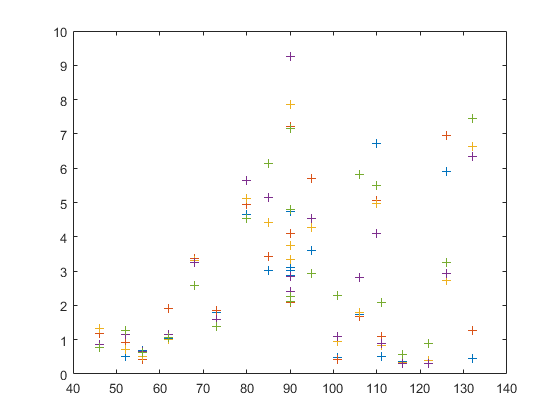

figure
plot(gnssData(:,2), gnssData(:,size(gnssData,2)), '+')
hold on
plot(gnssData(:,2),  gnssData(:,size(gnssData,2)-1), '+')
plot(gnssData(:,2), gnssData(:,size(gnssData,2)-2), '+')
plot(gnssData(:,2), gnssData(:,size(gnssData,2)-3), '+')
plot(gnssData(:,2), gnssData(:,size(gnssData,2)-4), '+')
hold off


Nvalid = size(gnssData,1);
% choose = [1 2 7 8 9 10 14 18 19 24 31 37];
% choose = [1 2 7 8 22 27 33];
% choose = 1:6;
% plot(gnssData(choose,size(gnssData,2)), gnssData(choose,size(gnssData,2)-1), 'r+')



